# Dereverberation

[signal, fs] = audioread('EchoSample.mp3')

signal =     0.0019    0.0018
    0.0028    0.0027
    0.0031    0.0027
    0.0036    0.0031
    0.0037    0.0033
    0.0032    0.0024
    0.0030    0.0020
    0.0032    0.0027
    0.0036    0.0036
    0.0041    0.0042


fs = 44100

% Take only the left channel from the stereo recording
signal = signal(:, 1)

signal =     0.0019
    0.0028
    0.0031
    0.0036
    0.0037
    0.0032
    0.0030
    0.0032
    0.0036
    0.0041


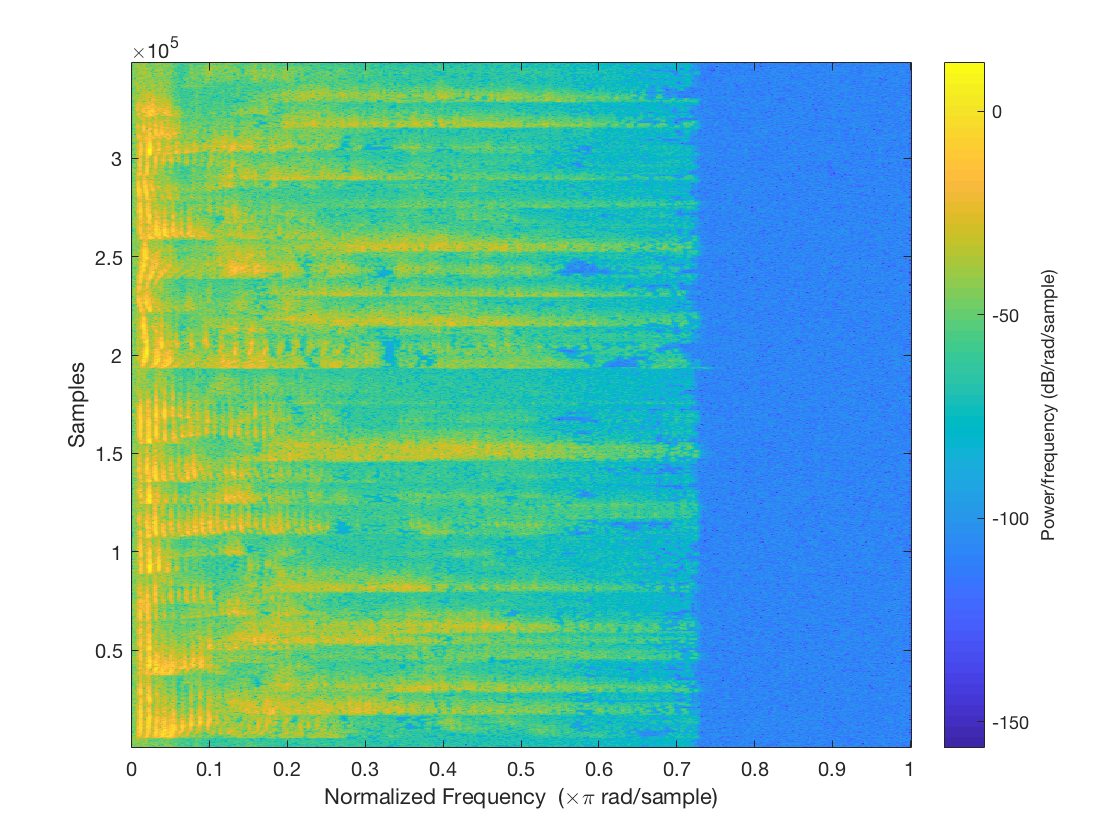

% Compute the signal's STFT with nfft=1024
% and a 50% overlapping Hann window.
stftWindowSize = 1024;
overlap = 0.5;
[M,w,t] = spectrogram(signal, hann(stftWindowSize), overlap*stftWindowSize); %, fs)
spectrogram(signal, hann(stftWindowSize), overlap*stftWindowSize)

% M ('microphone') - input signal (reverberated) frequency-domain vectors.
% Rows - frequencies, Columns - time frames (middle time-point)

% Impulse response block length - has to be 'sufficiently small'
% TODO: experiment with value. Is this really the same as the window size?
D = stftWindowSize;
[frequencyCount, frameCount] = size(M);
B = 10; % Number of impulse response blocks - 1. TODO: experiment.

S = zeros(size(M)); % Dry signal frequency-domain vectors.
R = zeros(size(M)); % Reverberated components frequency-domain vectors.
% Minimum gain per frequency. TODO: Should be frequency specific? Experiment.
minGain = zeros(frequencyCount, 1);

H = zeros(frequencyCount, B+1); % Frequency response estimate blocks
%energy = @(signal) sum(abs(signal).^2);
energy = @(signal) abs(signal).^2;

previousFrames = zeros(frequencyCount, B); % Most recent previous frame is first.
for frameIndex=1:frameCount
    frame = M(:, frameIndex);
    G_S = 1 - (sum(energy(previousFrames) .* energy(H(:, 2:end)))) ./ energy(frame);
    % Enforce a minimum gain for each frequency.
    G_S = max([G_S minGain], [], 2);
    G_R = 1 - G_S;
    % TODO: Apply gain smooting over time to G_S and G_R.
    S(:, frameIndex) = G_S .* frame;
    R(:, frameIndex) = G_R .* frame;
    
    % Shift each row one position to the right.
    circshift(previousFrames, 1, 2);
    previousFrames(:, 1) = frame;
end

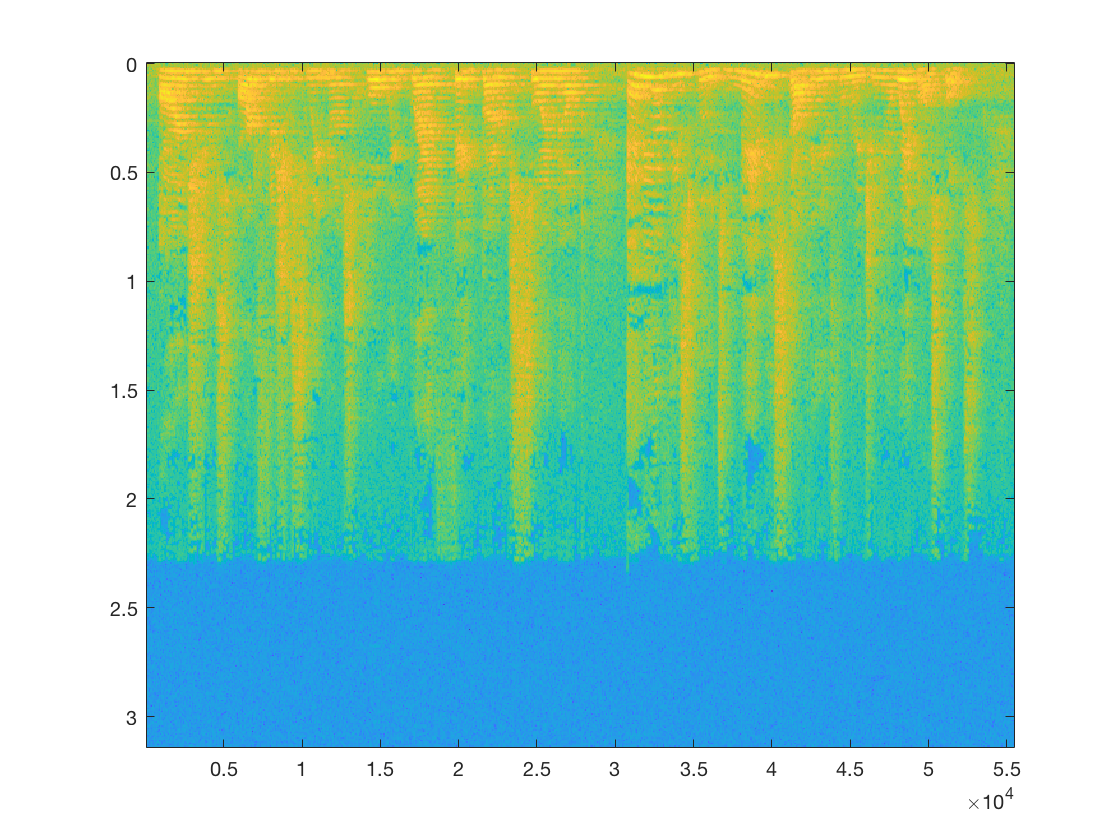

% Display the spectrum power before and after:
figure;
imagesc(t, w, 10*log10(abs(M)+eps));

figure;
imagesc(t, w, 10*log10(abs(S)+eps));